clear
clf

NumAng=90;
angle=[0:180/NumAng:180-180/NumAng]

angle =      0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98


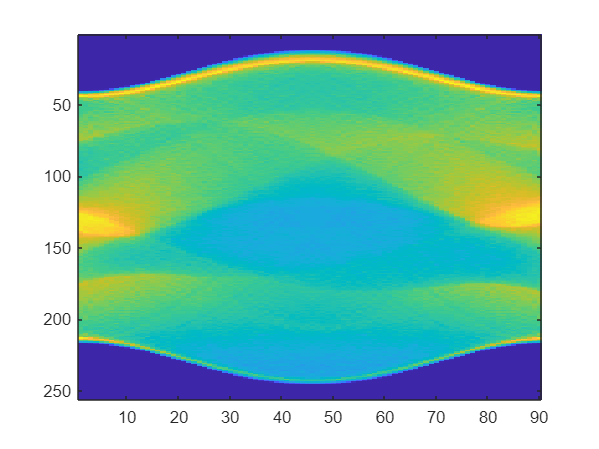


p=phantom(256);
for i=1:NumAng
    pr=imrotate(p,angle(i),'crop');
    R(:,i)=sum(pr);
end

%R=radon(p,angle,256);
angle=[0:180/NumAng:180-180/NumAng]*pi/180;
imagesc(R);

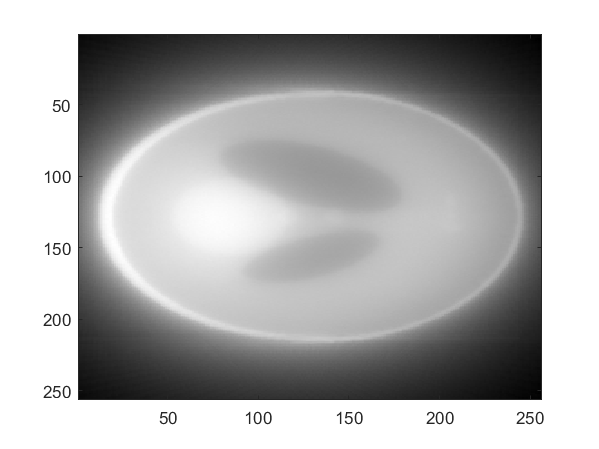


% Back Projection
f=zeros(256,256);
for    theta=1:NumAng
    for i=1:256
        for j=1:256
            t=floor((i-128)*cos(angle(theta))+(j-128)*sin(angle(theta))+128);
            if t<=0
                t=1;
            end
            if t>256
                t=256;
            end
             f(i,j)=f(i,j)+R(t,theta);
        end
    end
    imagesc(f),colormap(gray)  % To visualize Uncomment
    pause(0.5);
end

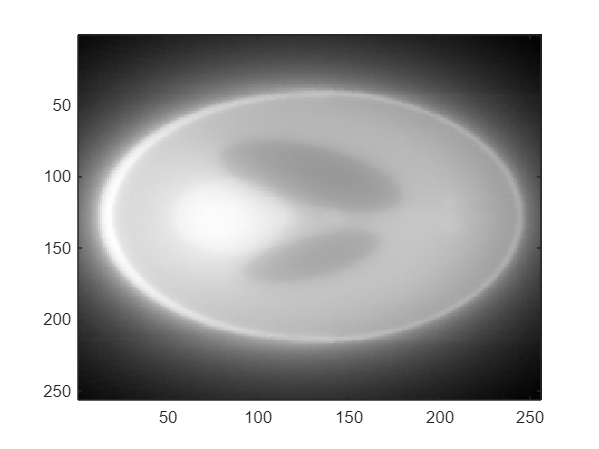

figure(1),imagesc(f),colormap(gray)